y=randn([1,500])

y =    -1.3077   -0.4336    0.3426    3.5784    2.7694   -1.3499    3.0349    0.7254   -0.0631    0.7147   -0.2050   -0.1241    1.4897    1.4090    1.4172    0.6715   -1.2075    0.7172    1.6302    0.4889    1.0347    0.7269   -0.3034    0.2939   -0.7873    0.8884   -1.1471   -1.0689   -0.8095   -2.9443    1.4384    0.3252   -0.7549    1.3703   -1.7115   -0.1022   -0.2414    0.3192    0.3129   -0.8649   -0.0301   -0.1649    0.6277    1.0933    1.1093   -0.8637    0.0774   -1.2141   -1.1135   -0.0068


x=2+5*y

x =    -4.5384   -0.1680    3.7131   19.8920   15.8472   -4.7494   17.1746    5.6270    1.6847    5.5737    0.9752    1.3793    9.4485    9.0452    9.0860    5.3575   -4.0374    5.5862   10.1512    4.4445    7.1735    5.6344    0.4828    3.4694   -1.9364    6.4420   -3.7354   -3.3444   -2.0475  -12.7214    9.1919    3.6260   -1.7746    8.8515   -6.5576    1.4888    0.7928    3.5960    3.5643   -2.3244    1.8497    1.1756    5.1385    7.4663    7.5464   -2.3183    2.3868   -4.0706   -3.5675    1.9658


mean(x)

ans = 1.8915

std(x)

ans = 4.9761


t_h=[0,1];
tose=randi(t_h,1,5000)

tose =      1     1     1     0     0     0     0     0     0     0     1     1     1     1     1     0     0     1     0     1     1     1     0     0     1     1     1     0     0     1     0     0     1     0     0     1     0     1     0     1     1     0     0     0     0     0     0     1     0     1


sum=cumsum(tose)

sum =      1     2     3     3     3     3     3     3     3     3     4     5     6     7     8     8     8     9     9    10    11    12    12    12    13    14    15    15    15    16    16    16    17    17    17    18    18    19    19    20    21    21    21    21    21    21    21    22    22    23


t=[1:5000];
probability=sum./t

probability =     1.0000    1.0000    1.0000    0.7500    0.6000    0.5000    0.4286    0.3750    0.3333    0.3000    0.3636    0.4167    0.4615    0.5000    0.5333    0.5000    0.4706    0.5000    0.4737    0.5000    0.5238    0.5455    0.5217    0.5000    0.5200    0.5385    0.5556    0.5357    0.5172    0.5333    0.5161    0.5000    0.5152    0.5000    0.4857    0.5000    0.4865    0.5000    0.4872    0.5000    0.5122    0.5000    0.4884    0.4773    0.4667    0.4565    0.4468    0.4583    0.4490    0.4600


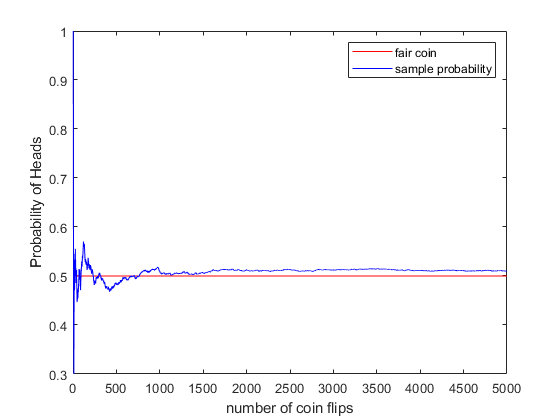

plot(t,0.5*ones(1,5000),"r")
hold on 
plot(t,probability,'b')
xlabel("number of coin flips")
ylabel("Probability of Heads")
legend("fair coin", "sample probability")
hold off


clear

p=poissrnd(5,1,1000)

p =      1     4     5     3     3     3     6     3     5     4     4     6     1     5     6    10     6     6     5     7     4     1     6     4     4    10     6     4     5     3     4     4     6     5     2     3     3     6     5     8     5     5     7     5     7    12     8     3    10     5


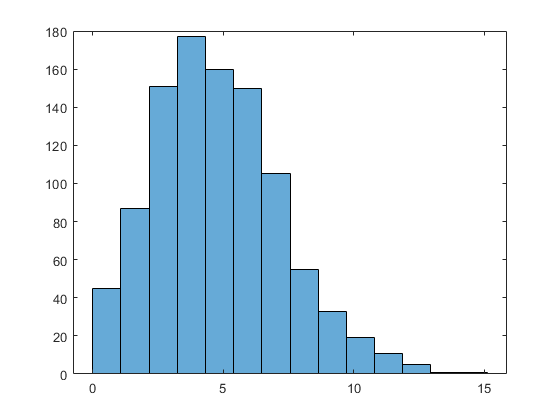

histogram(p,14)
hold on 

d=poisspdf(p,5)

d =     0.0337    0.1755    0.1755    0.1404    0.1404    0.1404    0.1462    0.1404    0.1755    0.1755    0.1755    0.1462    0.0337    0.1755    0.1462    0.0181    0.1462    0.1462    0.1755    0.1044    0.1755    0.0337    0.1462    0.1755    0.1755    0.0181    0.1462    0.1755    0.1755    0.1404    0.1755    0.1755    0.1462    0.1755    0.0842    0.1404    0.1404    0.1462    0.1755    0.0653    0.1755    0.1755    0.1044    0.1755    0.1044    0.0034    0.0653    0.1404    0.0181    0.1755


i=interp1(p,d,(0:0.1:max(p)))

Error using matlab.internal.math.interp1
Sample points must be unique and sorted in ascending order.

Error in interp1 (line 154)
        VqLite = matlab.internal.math.interp1(X,V,method,method,Xqcol);

plot((0:0.1:max(p)),i,'r')
hold off

k=[0:0.001:2*pi]
j=sin(k)
plot(k,j,'r')
xlim([0,2*pi])

set(gca,'xTick',[0 pi 2*pi])
set(gca,'xTicklabel',{'0' '1' '2'})
set(gca,'yTick',[-1:0.5:1])
grid on
set(gca,'ycolor','g')
set(gca,'xcolor','c')
set(gca,'color','k')
set(gcf,'color',[0.5 0.5 0.5])
title('One sine wave from 0 to 2π',"FontSize",14,"FontWeight","bold","Color",'w')
xlabel('X values (in terms of \pi)',"FontSize",12,"Color",'c')
ylabel('Sin(x)',"FontSize",12,"Color",'g')




